Ryan Fahrenkrug

MECH 105

Homework 11

10/2/2017

Purpose: This code estimates the diameter of a stone being skiped across the water. 

v=0.8; % Velocity in m/s
M=0.1; % Mass in kg
C=1; % Coefficient
pw=1000; % Water density in kg/m^3
b=10; % Incidence angle in degrees
g=9.81; % Gravity in m/s^2
theta=10; % Tilt angle in degrees
% Function used determine d when f(d)=0
func= @(d) sqrt((16.*M.*g)./(pi().*C.*pw.*d.^2))./sqrt(1-(8.*M.*(tand(b)).^2)./(pi()*d.^3.*C.*pw.*sind(theta)))-v;

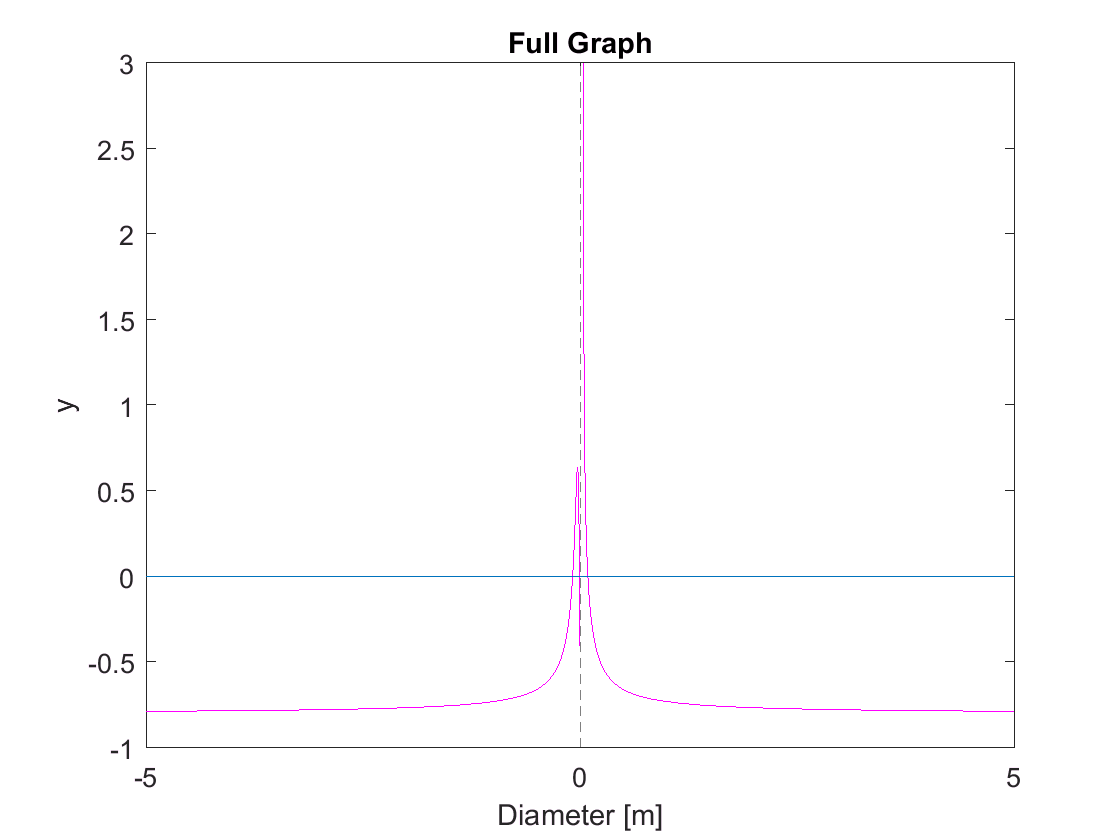

% Full graph
fplot(func,'m')
xlim([-5 5])
ylim([-1 3])
refline(0,0)
title('Full Graph')
xlabel('Diameter [m]')
ylabel('y')

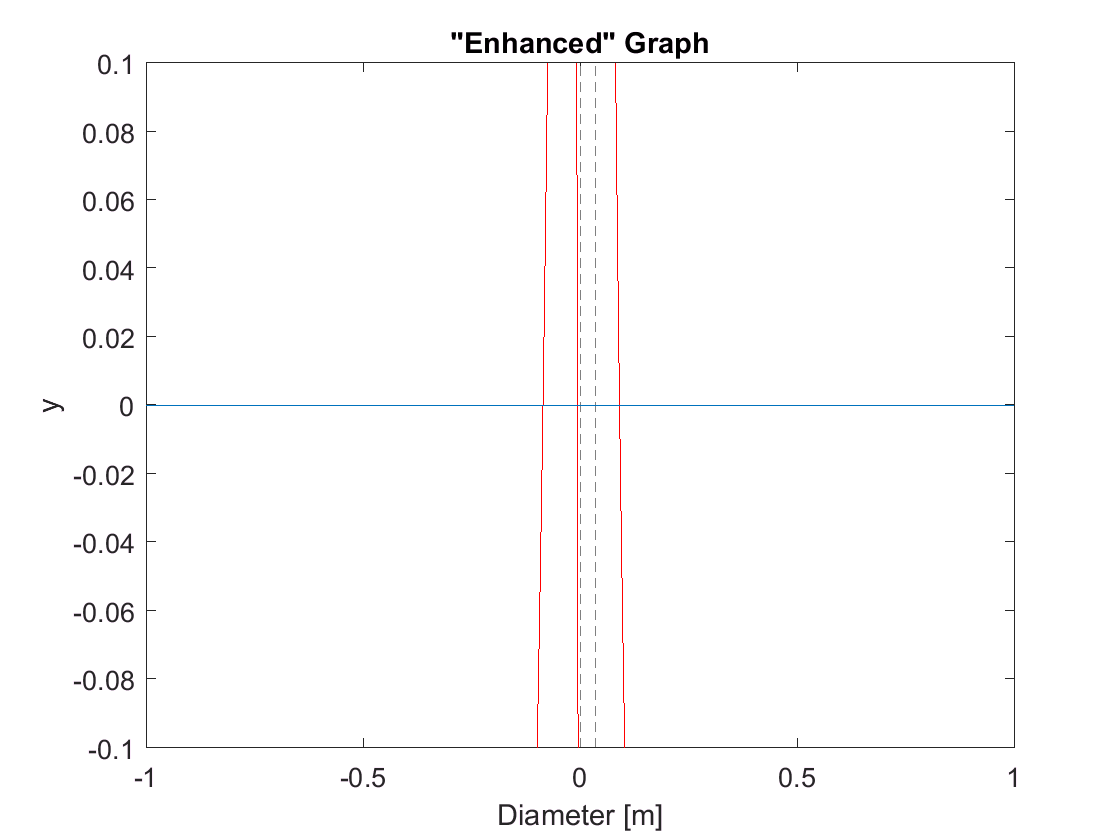

% Enhanced by IT guy graph ;D
fplot(func,'r')
xlim([-1 1])
ylim([-.1 .1])
refline(0,0)
title('"Enhanced" Graph')
xlabel('Diameter [m]')
ylabel('y')

% The diameter of the rock is... 
d=fzero(func,.1);
fprintf('The diameter of the rock is %1.4f meters.\n',d)

The diameter of the rock is 0.0911 meters.
